# ROOM ACUSTICS:

## Chapter 2: Statistical Room Acoustics.

### Reverberation Time: 

Let us calculate the reverberation time of a room acording to Sabine and Eyring. The Spanish Building Code specifies that the Sabine Equation must be used to calculate the reverberation time in an proyect in order to check if the room meets the specification given in the regulations. The influence of the air absortion in the cacuations are also checked. 

f=[125 250 500 1000  2000 4000]; % Frequency in octave bands. 

Some real absorption coefficients can be obtained from the internet:

- Acoustic ceilings: [Heraklith](https://www.heraklith.es/sites/es.heraklith.knaufinsulation.net/files/download/files/heraklith_ficha_technica_tektalan_a2_02_2018.pdf), Pladurfon [Pladurfon](https://www.pladur.es/es-ES/download/file/es/3109e937334f4dfe8caca9b9008302f5/manual-tecnico-pladur-2020?rev=8b3a0c0e-bb8e-4345-9326-37a88185cdbc), [Eurocoustic](https://www.eurocoustic.es/fichas-tecnicas)

- Acosutic panels: [Ecophon](https://www.ecophon.com/es/ecophon/wall-applications/akusto/akusto-wall-a/)

- Wood panels: [Molduras del Noroeste](https://www.grupomolduras.com/wp-content/uploads/PRODUCTOS-GrupoMolduras.pdf)

- Absorption coef. at: [Tabla de coeficientes](https://www.bunker-audio.com/bunker-audio-portal-sonido-documentos.php?id=3)

It should be noticed that manufacturers publishes absorption coefs. in 1/1 octave band frequencies up to 4000 Hz.

Next, lets us calculate the reverberation time using some of those values obteined from different sources: 

alpha_ceiling=[0.5 0.65 0.65 0.65 0.5 0.5 ]; % FON+ R Aleat. 8-15-20 BC  -  PLÉNUM 200 mm
%alpha_ceiling=[0.015 0.015 0.02 0.028 0.04 0.05 ]; 
alpha_wall1=[0.015 0.015 0.02 0.028 0.04 0.05 ]; % Brick walls with gypsum lining. 
alpha_wall2= [0.015 0.015 0.02 0.028 0.04 0.05 ];
alpha_wall3= [0.015 0.015 0.02 0.028 0.04 0.05 ];
alpha_wall4= [0.015 0.015 0.02 0.028 0.04 0.05 ];
alpha_floor= [0.09 0.09 0.08 0.09 0.1 0.05 ]; % Wood

alpha=[alpha_ceiling; alpha_wall1; alpha_wall2; alpha_wall3; alpha_wall4; alpha_floor];

% Room Dimensions:
l= 14;
width= 7; 
heigth= 3.5; 
V=l*width*heigth;

% Surfaces S=[Ceiling Wall1 Wall2 Wall3 Wall4 Floor]; 
S=[width*l l*heigth width*heigth l*heigth width*heigth width*l];
St=sum(S);          % Total surface

Equivalent Absorption Area, A: 


$$A=\sum_i \alpha_{i\;} \cdot S_i$$
 

A=sum(alpha.*S',1); 

Mean absorption: 

alpham=A/St;

#### Sabine equation:


$$T=0.161 \frac{V}{A+ 4mV}$$


Ts=0.161*V./A;

#### Eyring equation:


$$T=-0.161 \frac{V}{S \ln (1-\bar{\alpha})+4mV}
$$


Te=-0.161*(V./(St*log(1-alpham)));

#### Sabine versus Eyring: 

The next plot shows that the values obtained using Eyring's Equations are always higher than those calculated using Sabine's Equation. Then, using Sabine could overestimate the values of the reverberation time which can be good if meeting a limit specified by regulations is required.  

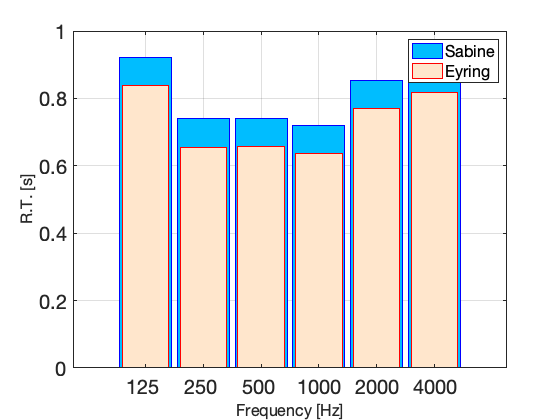

% Plotting Reverb Time as function of the 1/1 octave band frequencies: 
pos=1:length(f);
h=bar(pos,Ts,0.9,'EdgeColor','b','FaceColor',[0 0.74 1]); grid;hold on;
h2=bar(pos,Te,0.8,'EdgeColor','r','FaceColor',[1 0.9 0.8]);
set(gca,'XTick',pos,'XTickLabel',f);
set(gca,'FontSize',20);
p=ylabel(['R.T. [s]'],'FontSize',16);
xlabel('Frequency [Hz]', 'FontSize',16); 
legend('Sabine','Eyring', 'Location','northeast','FontSize',16); hold off; 

#### Influence of temperature and humidity

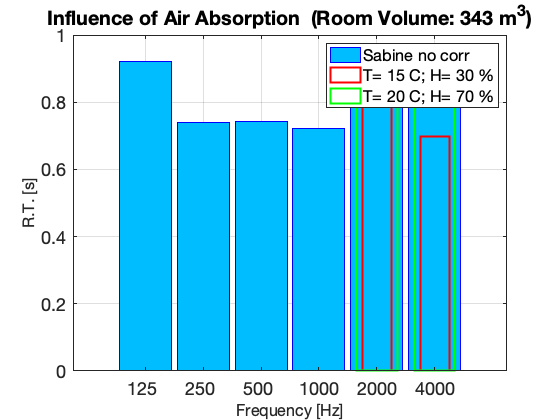

m4=[0.0147 0.0519  0.1144  0.1671 ;
0.0122   0.0411   0.0937   0.1431 ;
0.0111   0.0335   0.0759   0.1178 ;
0.0114   0.0292   0.0633   0.0975 ; 
0.0096   0.0309   0.0712   0.1102 ;
0.0092   0.0258   0.0577   0.0896 ;
0.0101   0.0234   0.0489   0.0748 ;
0.0119   0.0234   0.0443   0.0655 ; 
0.0081   0.0231   0.0519   0.0808 ;
0.0088   0.0208   0.0437   0.0671 ;
0.0105   0.0208   0.0396   0.0748 ;
0.0131   0.0231   0.0391   0.0548];
heigth=[30*ones(4,1); 50*ones(4,1); 70*ones(4,1)];
T=[15 20 25 30 15 20 25 30 15 20 25 30]';
%M4=zeros(12,10); 
% M4(:,7:10)=m4(:,1:4); % Uncomment this to calculate up to 8000
M4=zeros(12,8); 
M4(:,7:8)=m4(:,1:2);    % Only 2000 and 4000
M4(:,1:2)=[heigth T];

% Sabine RT with the influence of the factor 4mV:
Tsc=0.161*V./(A+M4(:,3:end)*V); % Change 4 by 'end' to calculate above 4000 Hz
h=bar(pos,Ts,0.9,'EdgeColor','b','FaceColor',[0 0.74 1]); grid;hold on;
h2=bar(pos(5:end),Tsc(1,5:end),0.5,'EdgeColor','r','FaceColor','none','LineWidth',2); hold on; 
h3=bar(pos(5:end),Tsc(10,5:end),0.7,'EdgeColor','g','FaceColor','none','LineWidth',2); 
legend('Sabine no corr',sprintf('T= %d C; H= %d %%',T(1),heigth(1)),sprintf('T= %d C; H= %d %% ',T(10),heigth(10)));
set(gca,'XTick',pos,'XTickLabel',f);
set(gca,'FontSize',18);
p=ylabel(['R.T. [s]'],'FontSize',16);
xlabel('Frequency [Hz]', 'FontSize',16); 
title(sprintf('Influence of Air Absorption  (Room Volume: %.0f m^3)',V)); 
hold off; 

## Sound Pressure Level:

Setup of acoustic quantities: 

%c= 343.9862;    % Sound Speed
%rho=1.1992;     % Air density
%Zo=rho*c;       % Acoustic Impedance of Air
c=344; rho=1.2; Zo=rho*c;
pref=2e-5;      % Reference for SPL

Source characteristics:

W=1e-3;                     % Acoustic Power of the Source in Watts.
Q=1;                        % Directivity
position=[l/2 width/2];     % Position of the Source Inside the Room. 

Select the frequency:

fc=1000;

#### Room constant, R:

$R= - \frac{S \cdot \ln (1-\bar{\alpha})}{1-\bar{\alpha}}
$,

R=-St*log(1-alpham)./(1-alpham);
Rf=R(f==fc);

#### Critical Distance, rh:


$$r_h=\frac{1}{4} \sqrt{\frac{R \; Q}{\pi}}$$


Rh=0.25*sqrt(R*Q/pi);

Next, let's show the sound field in terms of Statistical Theory is calculated. First, we define a grid of points inside the room and the distances, r,  between the field points and the source, are calculated:

Res=0.25;        % Resolution of the grid
x=0:Res:l; 
y=0:Res:width; 
[X,Y]=meshgrid(x,y);
r2=(X-position(1)).^2+(Y-position(2)).^2;  % Squared distance between field points and the Source

#### Direct  (free) field: 

The contribution of the direct field is : $\overline{p^2}_{dir}=\rho c \frac{W Q}{4 \pi r ^2}
$,

where *W *is the acoustic power of the source and Q the directivity factor. 

pd2=Zo*W*Q./(4*pi*r2);          % Direct Field

#### Reverberant field:

Once the room constant R is known, the contribution of the reverberant sound field can be calculated: 


$$\overline{p^2}_{rev}=\rho c W \frac{ 4}{R}
$$


prev2=Zo*W*4/Rf;                

The total sound pressure level inside the room is calculated by superposition of the direct and the reverberant field: 


$$\overline{p^2}_{t}=\overline{p^2}_{dir}+\overline{p^2}_{rev}
$$


Notice we are assuming that we are calculating the source level in terms of its rms sound pressure.

pt2=pd2+prev2;           

Now the SPL of each contribution can be calculated:

Ld=10*log10(pd2/pref^2);        % SPL direct sound field.
Lrev=10*log10(prev2/pref^2);    % SPL reverberant field.
Lp=10*log10(pt2./pref^2);       % Total Sound Pressure Level inside the room in dB

Surface plot of the SPL:

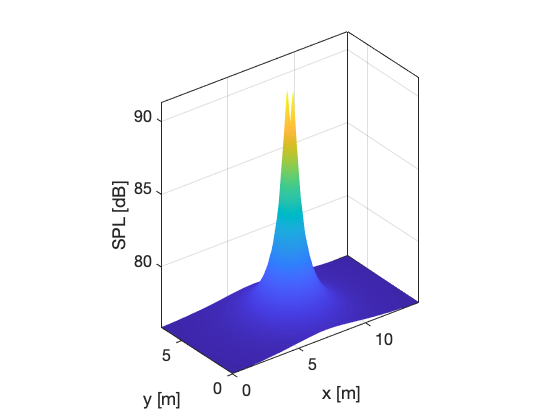

figure(1);
surf(X,Y,Lp,'FaceColor','interp','EdgeColor','none');
xlabel('x [m]'); ylabel('y [m]'); zlabel('SPL [dB]');
set(gca,'FontSize',16); axis equal; box on;

Let's see a side cut of the sound field and see the critical distance: 

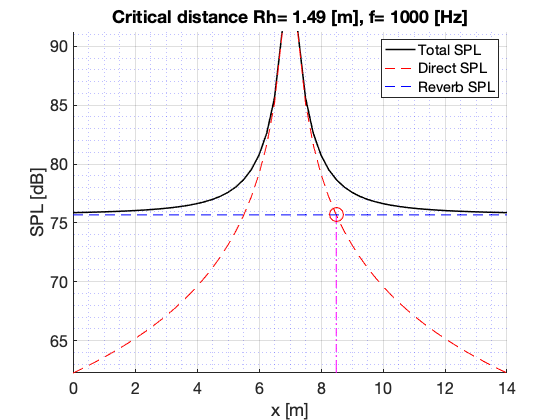

cutx=X(Y==position(2));         % Taking x values with y equals to the y-coord of the source.
Lpcut=Lp(Y==position(2));       % Taking the SPL values, total Sound pressure Level.       
Ldcut=Ld(Y==position(2));       % Direct SPL. 
figure(10);
ax=gca;
ax.NextPlot='add';
ax.MinorGridColor='b';
ax.MinorGridLineStyle=':';

plot(ax,cutx,Lpcut,'LineWidth',1.5,'Color','k'); plot(cutx,Ldcut,'Color','r','LineStyle','--'); 
plot(cutx,Lrev*ones(size(cutx)),'Color','b','LineStyle','--'); grid; grid minor;
xlabel('x [m]'); ylabel('SPL [dB]');

% Drawing a line at Rh  of the source position: 
hl=line((position(1)+Rh(f==fc))*ones(1,10),linspace(min(Ldcut)-10,Lrev,10),'LineStyle','-.','Color','m');

% Plotting a circle marking the intersection between the direct field and
% the reverberant field: 
plot(Rh(f==fc)+position(1),Lrev,'or','MarkerSize',14);

set(gca,'FontSize',16); hold off; legend('Total SPL','Direct SPL','Reverb SPL');
title(sprintf('Critical distance Rh= %.2f [m], f= %.0f [Hz]',Rh(f==fc),fc));
ylim([min(Ldcut) max(Ldcut)]);

*© Manuel A. Sobreira Seoane, January 2020. *